# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

Drone arms must be light enough to maximize the payload a quadcopter can carry, while remaining structurally strong enough to safely support motor thrust and weight without failing or deflecting excessively. This project explores how arm geometry and material choice together affect that trade-off, using MATLAB to quantify payload capacity and structural safety across multiple design and material options.

List the requirements, constraints, and success criteria for the project:

The drone must carry a minimum payload of 0.5 kg while maintaining a thrust to weight ratio of at least 2 to 1 for safe flight. Structurally, each arm design must achieve a factor of safety of at least 1.5 to 2 under the combined thrust and motor weight loading. Success means identifying at least one design and material combination that satisfies both the payload and structural safety requirements simultaneously, and using quantitative results to justify the final choice.

What is your proposed solution?

We evaluated two structurally distinct arm designs across six candidate materials, twelve combinations total, using a thrust to weight analysis to estimate maximum payload capacity for each combination, and finite element analysis to evaluate structural safety under load. Combining both analyses allowed us to identify which combinations actually met the payload requirement, and to select the strongest performer among those as our final recommendation.

List the steps you will need to take to achieve your proposed solution:

We first gathered material properties and defined our baseline drone parameters. We then proposed two arm designs and built 3D CAD models of each. We ran a thrust to weight analysis in MATLAB to calculate payload capacity for every design and material combination, which revealed that one of our two designs was too heavy to meet the minimum payload requirement regardless of material. We imported both CAD geometries into MATLAB's Structural Mechanics toolbox, applied boundary conditions and loads, and ran finite element analysis to compute displacement, stress, and factor of safety for each combination. Finally, we compared results across all combinations, ruled out designs and materials that failed the payload requirement, and selected the best performing option among those that remained.

What challenges do you face in the process of achieving the solution?

The biggest challenges were on the finite element analysis side. Correctly identifying the base and tip faces of irregular, real CAD geometry required writing custom automated logic rather than relying on manual face selection, since our imported parts had complex, non-flat surfaces near the mounting and motor mount ends. We also had to catch and correct a unit mismatch between our CAD geometry, exported in millimeters, and the meters and Pascals used throughout the rest of the analysis. We validated our results against a hand calculation to confirm our FEA setup was physically correct despite a solver warning about rigid body motion. Finally, our thrust to weight results showed that one entire design failed the payload requirement across nearly every material, which required us to reconsider our initial assumption that a stronger, more structurally optimized design would necessarily be the better choice.

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\mathrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

load droneArmMaterials.mat   % loads "materials" struct array, 6 materials
materialNames = {'Carbon Fiber Composite','Aluminum Alloy', ...
                  'Fiberglass Composite','PLA Plastic','ABS Plastic','Wood'};
 
g = 9.81;
numMotors = 4;
motorThrustMax = 1;     % kg thrust per motor
motorMass = 0.065;      % kg, single motor
baseMass = 1.0;         % kg, drone w/o arms or payload
minPayload = 0.5;       % kg
 
% Design 1 - arm CAD from partner, roughly 135.5mm long
design1.length = 0.1355;
design1.width = 0.010;
design1.thickness = 0.030;
design1.stlFile = 'DRONE_ARM.STL';
 
% Design 2 - second arm design, bigger cross section than design 1
design2.length = 0.1615;
design2.width = 0.0411;
design2.thickness = 0.0411;
design2.stlFile = 'DRONE_ARM2_SLDPRT.STL';
 
designs = {design1, design2};   % has to be a cell array since the two
                                 % structs don't have the same fields
designNames = {'Design 1', 'Design 2'};

## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

## Design 1

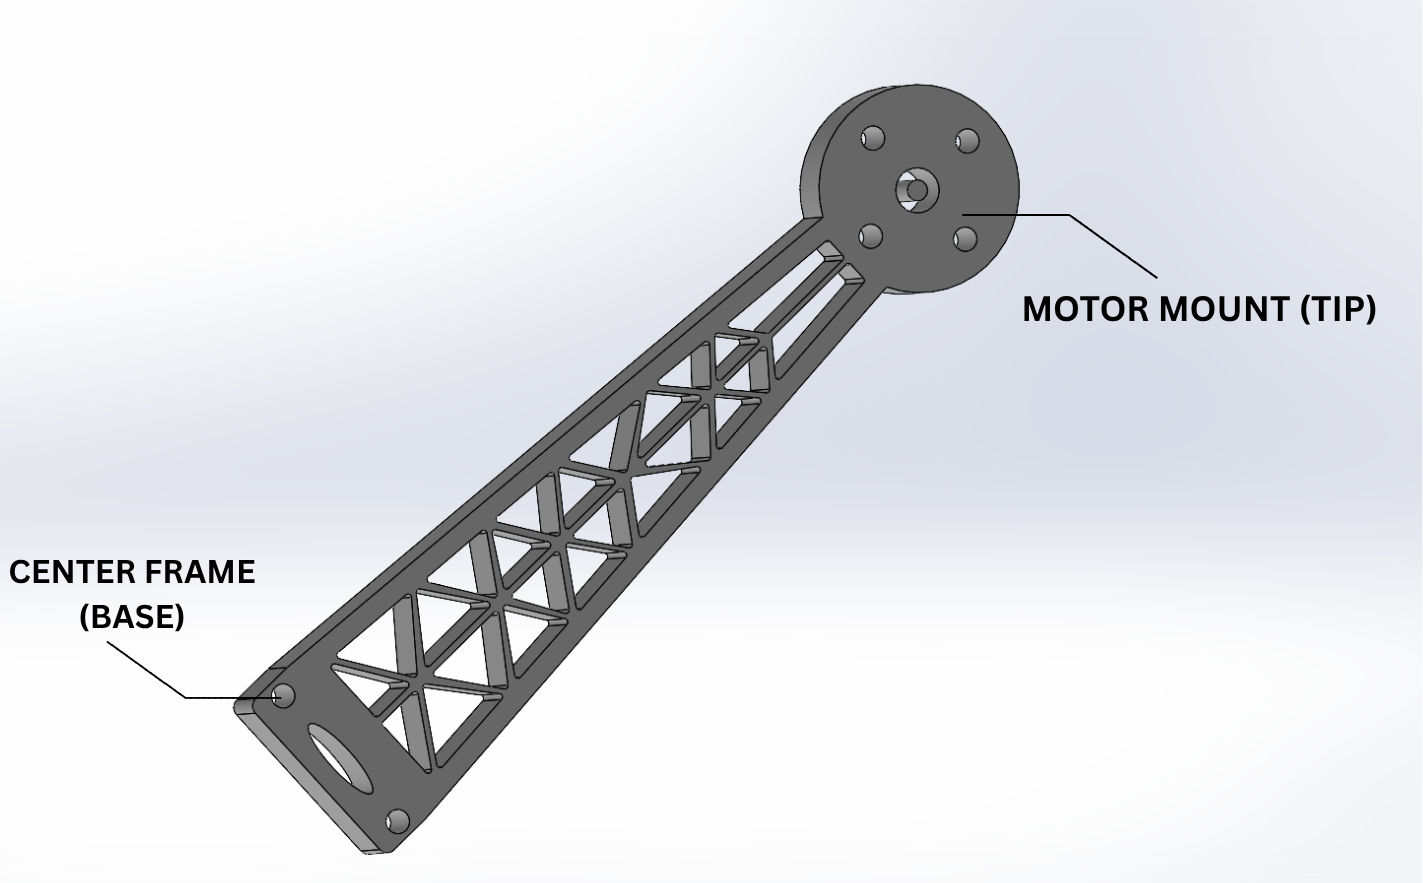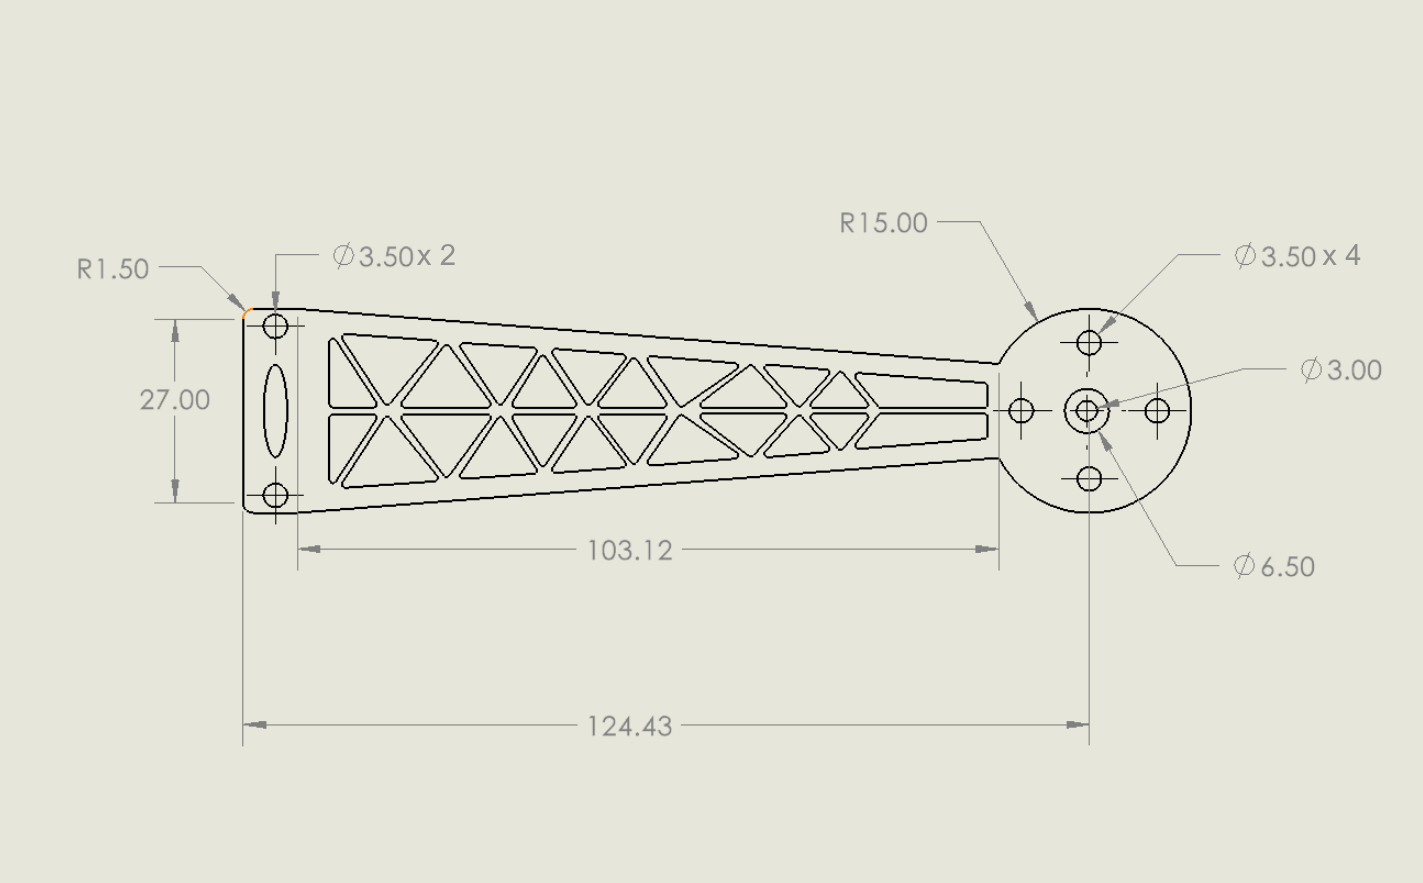

**Geometry:** Design 1 is a solid, contoured arm approximately 135.5 mm long with a nominal 10 mm × 30 mm cross-section. Instead of keeping the arm as a rectangular slab, the arm has a unique shape using cross-sectioned beams, with material removed in the empty spaces in order to reduce weight.

**Why we chose this design:** A solid cross-section provides a straightforward, sturdy connection between the drone body and motor, making it simpler for mounting. We wanted to prioritize stiffness and simplistic while also adding a bit of complexity through the crossing of the center beams.

**Expected/actual performance under load:** We expected this design to be stiff under the applied thrust load given its solid cross-section, with the highest stress located near the base, where the most bend is possible. Our results confirmed that our design was stiff, seeing as our max displacement stayed under 5×10⁻⁶ m for stiff materials like carbon fiber and aluminum; while the factor of safety was greater than 300 for every material except the plastics. This ultimately let us know that the design was overdone with excess materials, greater than what we actually needed.

## Design 2

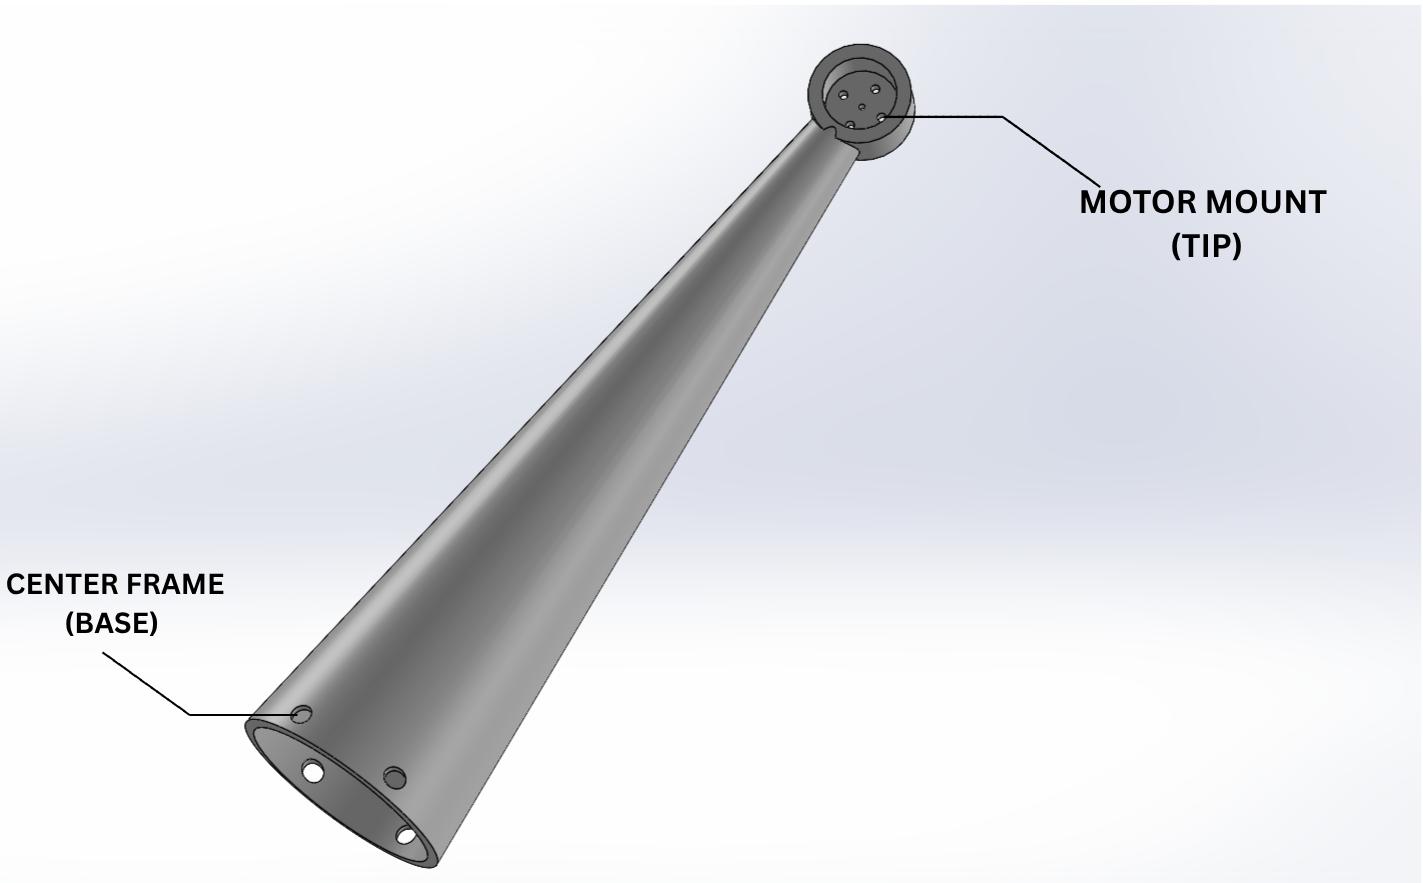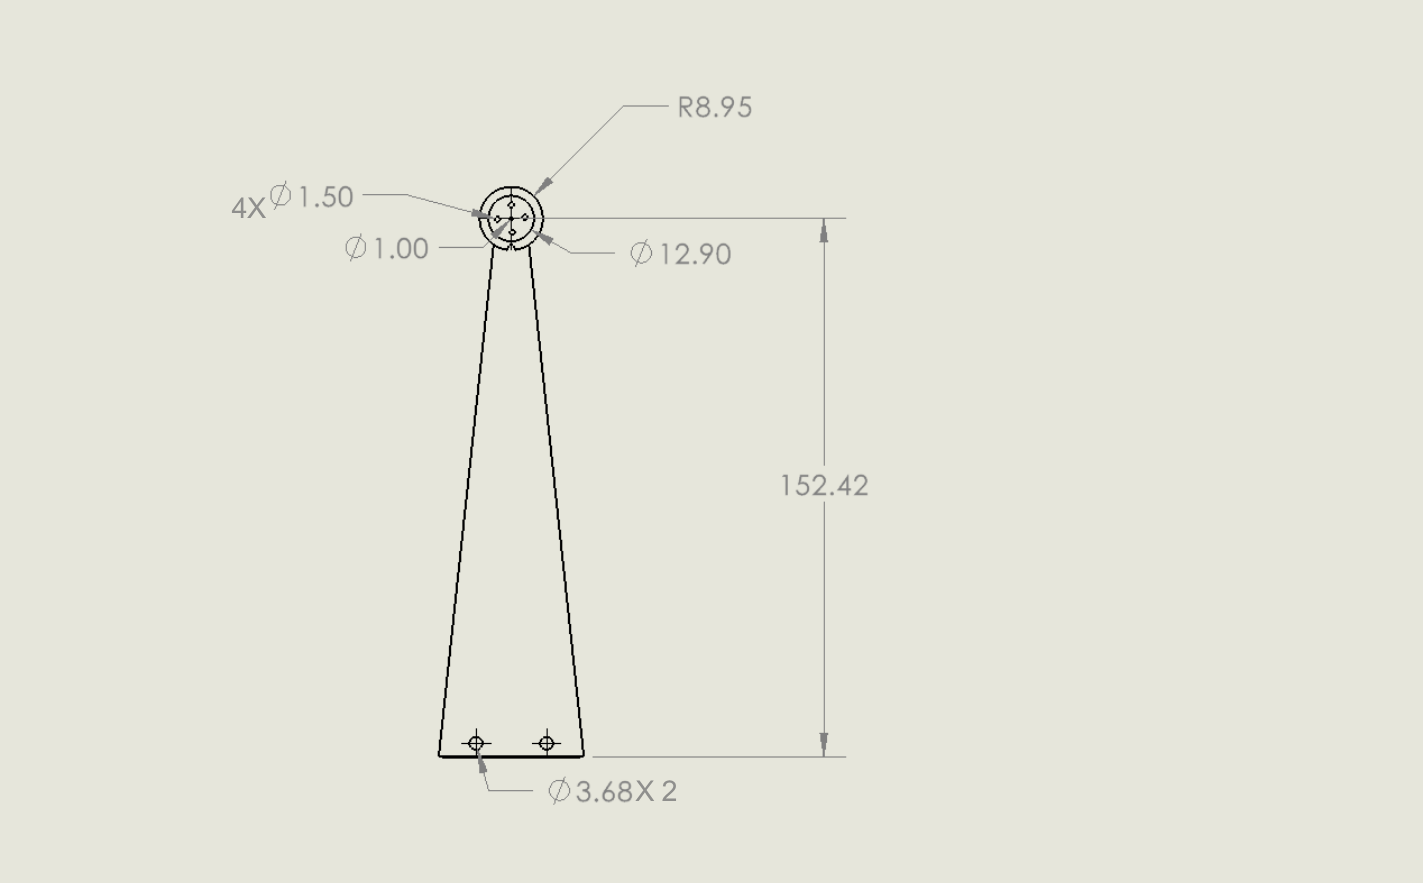

**Geometry:** Design 2 is a variant of a solid arm design we proposed. It is approximately 161.5 mm long with a roughly 41 mm × 41 mm bounding cross-section. This makes it quite bulky in comparison to Design 1, which had loads of empty space to spare material and weight.

**Why we chose this design:** We wanted to have a direct comparison with design 1's lighter-weight design by creating a more full and bulky arm. This would serve as a direct opposing strategy than the previous we tested, which would gibe us an idea of how a heavier drone arm would affect the relationship between payload cost, overall strength, and stiffness. 

**Expected/actual performance under load:** Given that the design was overall larger than the previous design, we expected design 2 to be overall stiffer and experience less total stress than design 1. From our results, we were able to see that the displacement was low, especially in comparison to design 1, across all used materials. At the same time, the peak stress seen in the design was actually higher than design 1 (e.g. ~1.11 MPa vs. ~0.89 MPa for carbon fiber).This meant that the factor of safety had been lowered in comparison to design 1, even with the bulkier design. We felt that this likely would have been caused due to certain stress concentrations in localized areas of our designs in the CAD, instead of stress induced bending. 

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

resultsT3 = thrustToWeightAnalysis(designs, materials, baseMass, ...
                                    numMotors, motorThrustMax, minPayload);
 
resultsT3.MaterialName = materialNames(resultsT3.Material)';
resultsT3 = resultsT3(:, {'Design','MaterialName','ArmMass_kg', ...
                           'TotalArmMass_kg','DroneMass_noPayload_kg', ...
                           'MaxPayload_kg','MeetsMinPayload'});
disp(resultsT3)

    Design           MaterialName           ArmMass_kg    TotalArmMass_kg    DroneMass_noPayload_kg    MaxPayload_kg    MeetsMinPayload
    ______    __________________________    __________    _______________    ______________________    _____________    _______________

      1       {'Carbon Fiber Composite'}      0.06504         0.26016                1.2602               0.73984            true      
      1       {'Aluminum Alloy'        }      0.10975         0.43902                 1.439               0.56098            true      
      1       {'Fiberglass Composite'  }     0.077235         0.30894                1.3089               0.69106            true      
      1       {'PLA Plastic'           }     0.050812         0.20325            

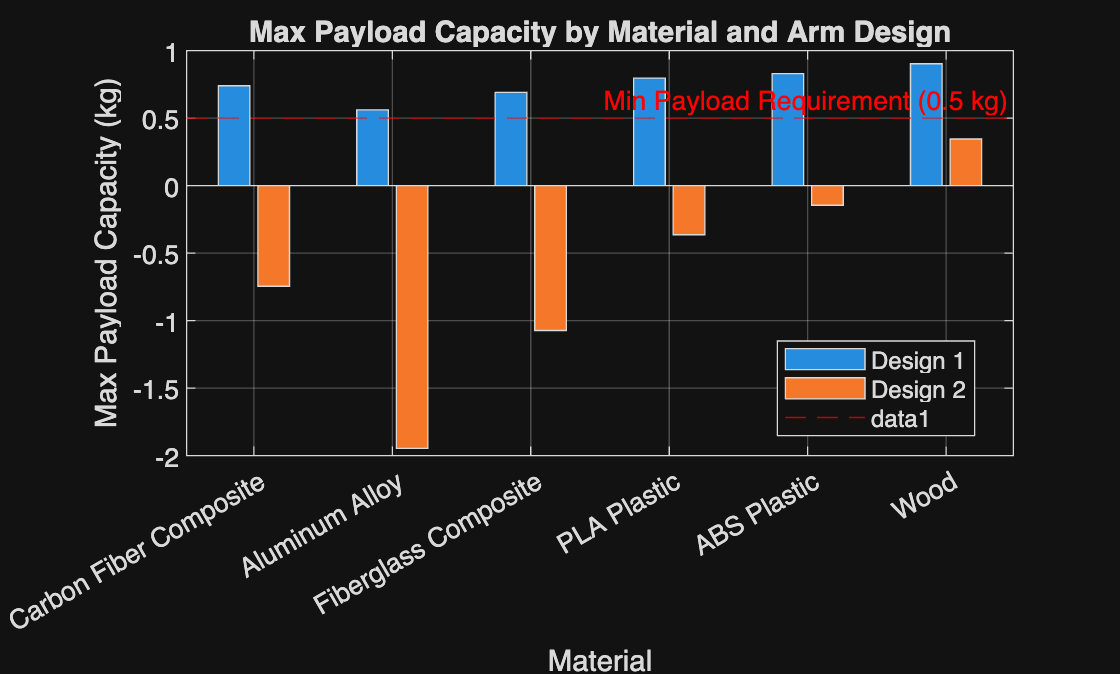

 
nD = numel(designs);
nM = numel(materials);
payloadMatrix = reshape(resultsT3.MaxPayload_kg, nM, nD);
 
figure;
bar(payloadMatrix);
set(gca, 'XTickLabel', materialNames, 'XTickLabelRotation', 30);
xlabel('Material');
ylabel('Max Payload Capacity (kg)');
title('Max Payload Capacity by Material and Arm Design');
legend(designNames, 'Location', 'best');
yline(minPayload, '--r', 'Min Payload Requirement (0.5 kg)');
grid on;

## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\mathrm{FoS}=\frac{\mathrm{Material}\;\mathrm{Yield}\;\mathrm{Strength}\;\left(\mathrm{Pa}\right)}{\mathrm{Maximum}\;\mathrm{von}\;\mathrm{Mises}\;\mathrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

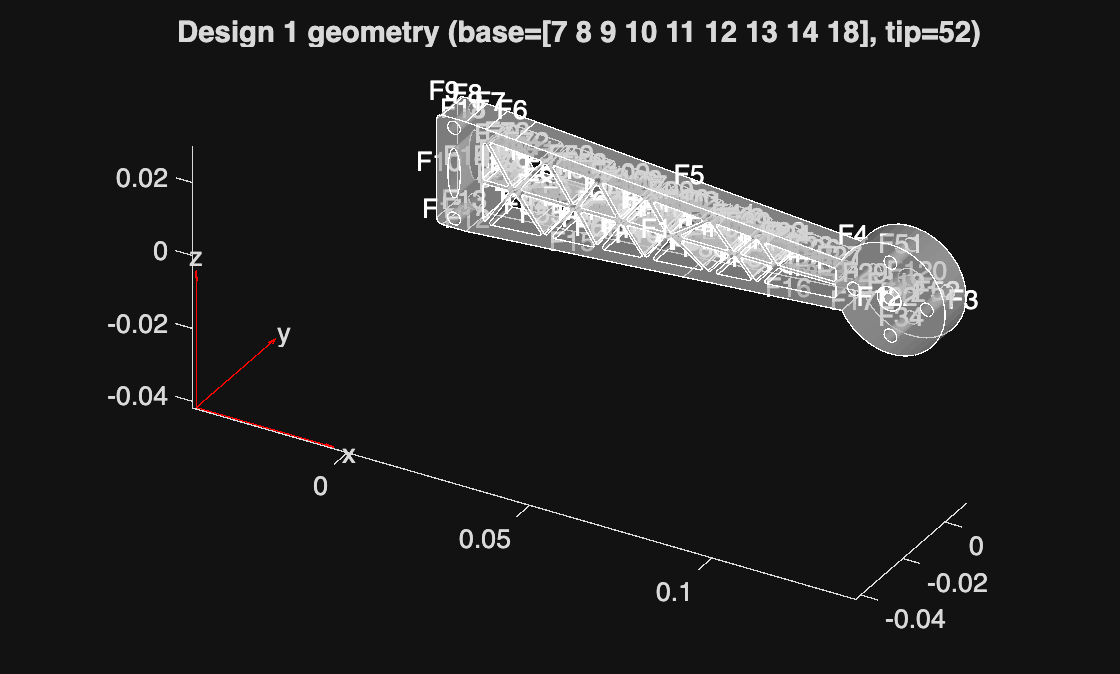

Design 1, Carbon Fiber Composite: maxDisp=4.88175e-06 m, maxVM=892696 Pa, FoS=672


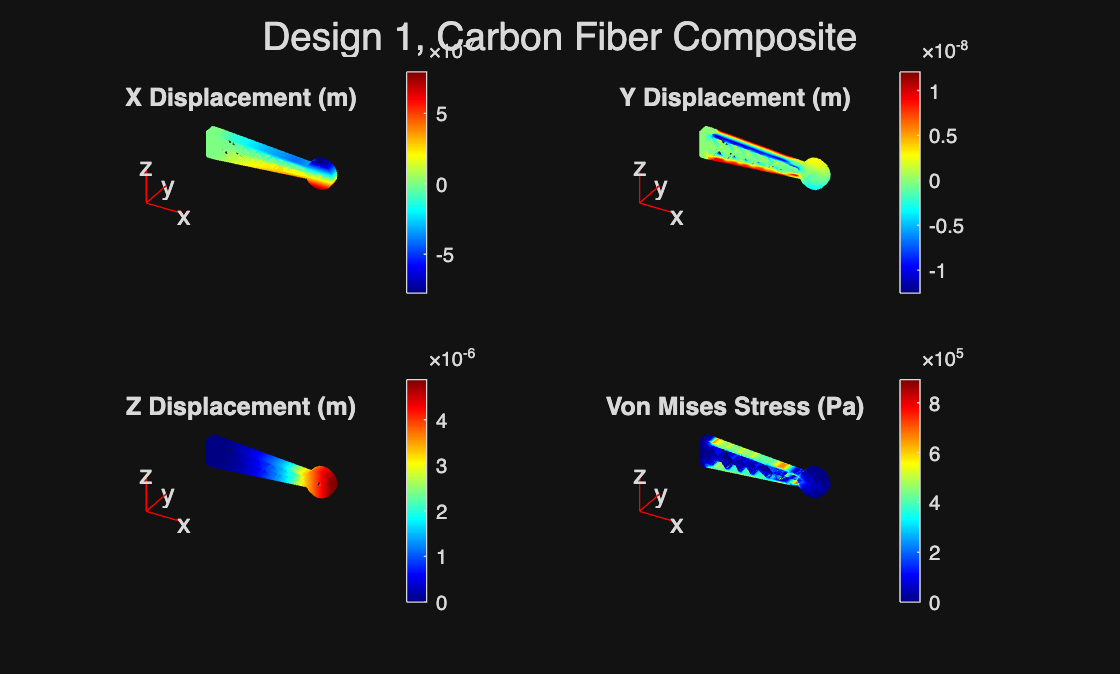

Design 1, Aluminum Alloy: maxDisp=4.9433e-06 m, maxVM=877959 Pa, FoS=313


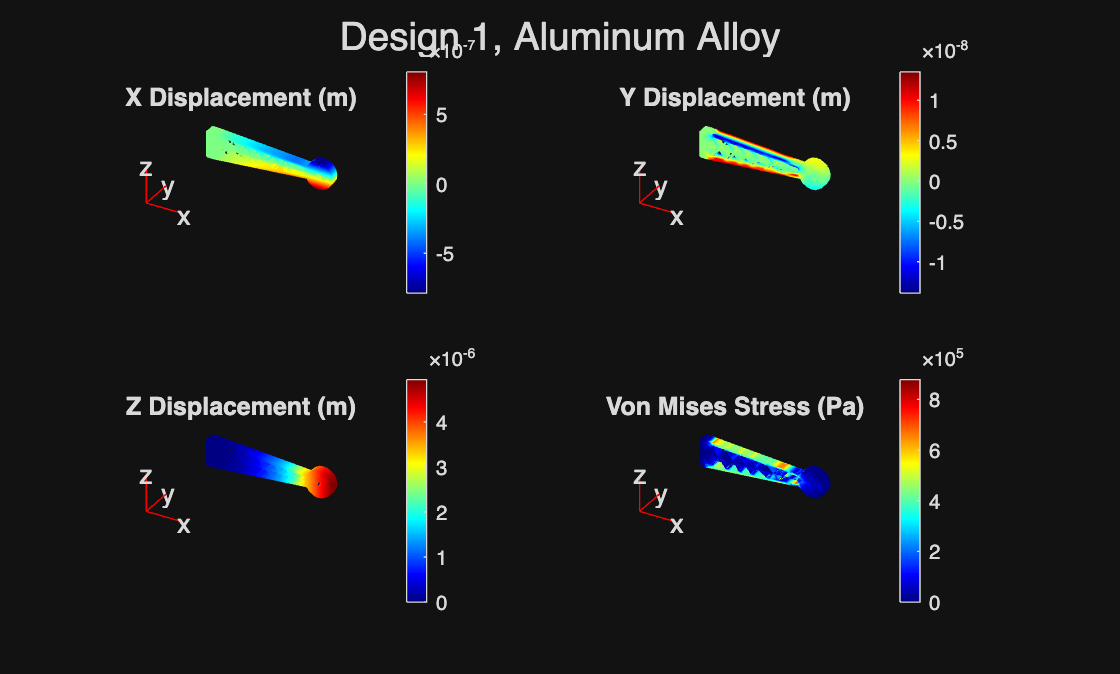

Design 1, Fiberglass Composite: maxDisp=1.36835e-05 m, maxVM=902249 Pa, FoS=333


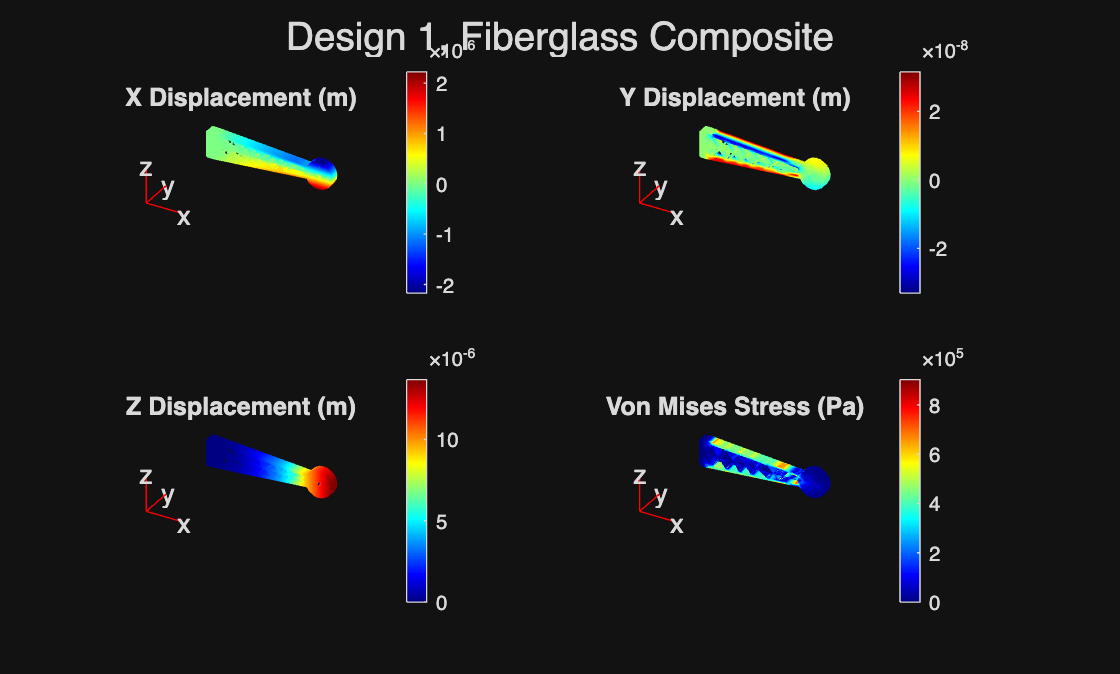

Design 1, PLA Plastic: maxDisp=9.72381e-05 m, maxVM=862572 Pa, FoS=69.6


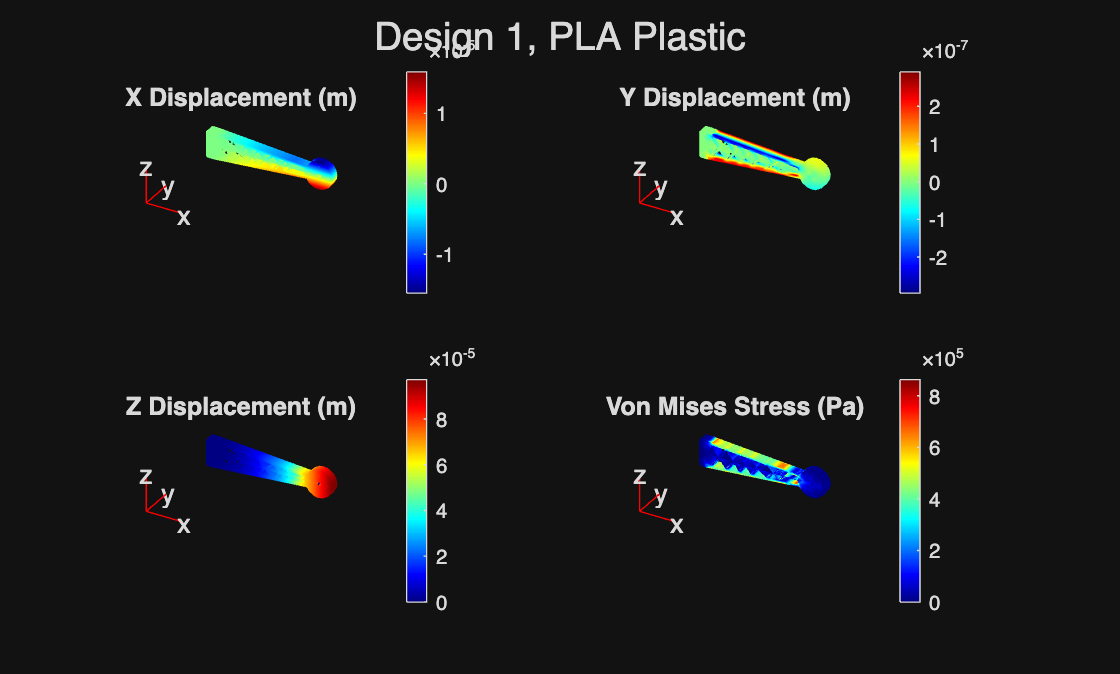

Design 1, ABS Plastic: maxDisp=0.0001703 m, maxVM=867788 Pa, FoS=46.1


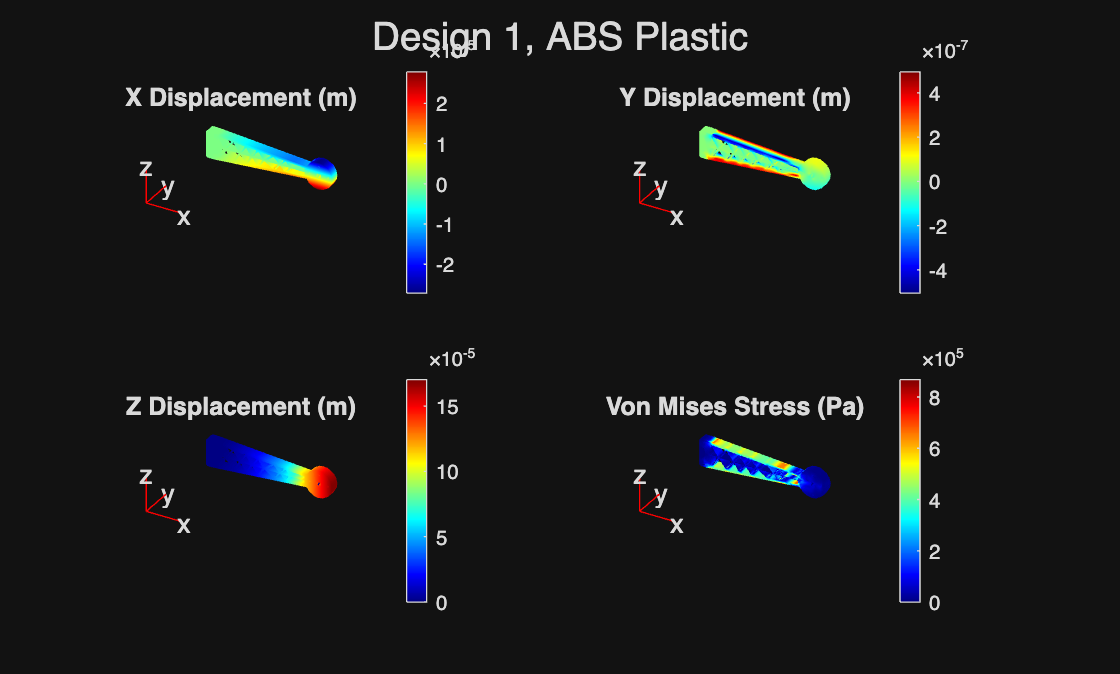

Design 1, Wood: maxDisp=3.406e-05 m, maxVM=867788 Pa, FoS=92.2


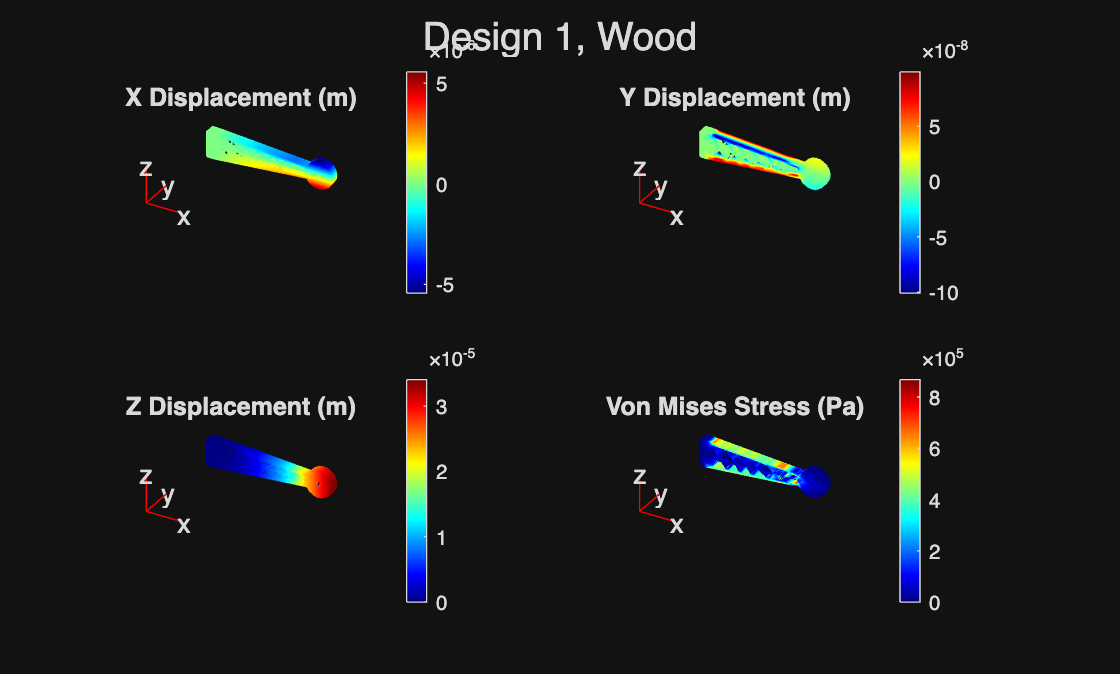

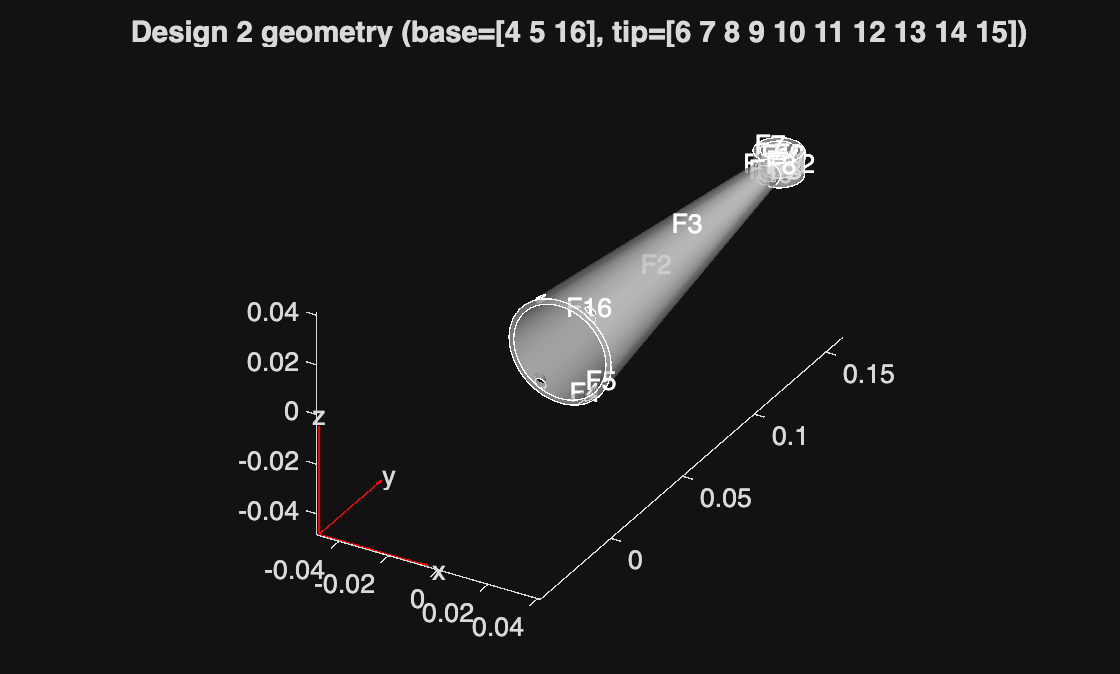

Design 2, Carbon Fiber Composite: maxDisp=1.05008e-05 m, maxVM=3.80198e+06 Pa, FoS=158


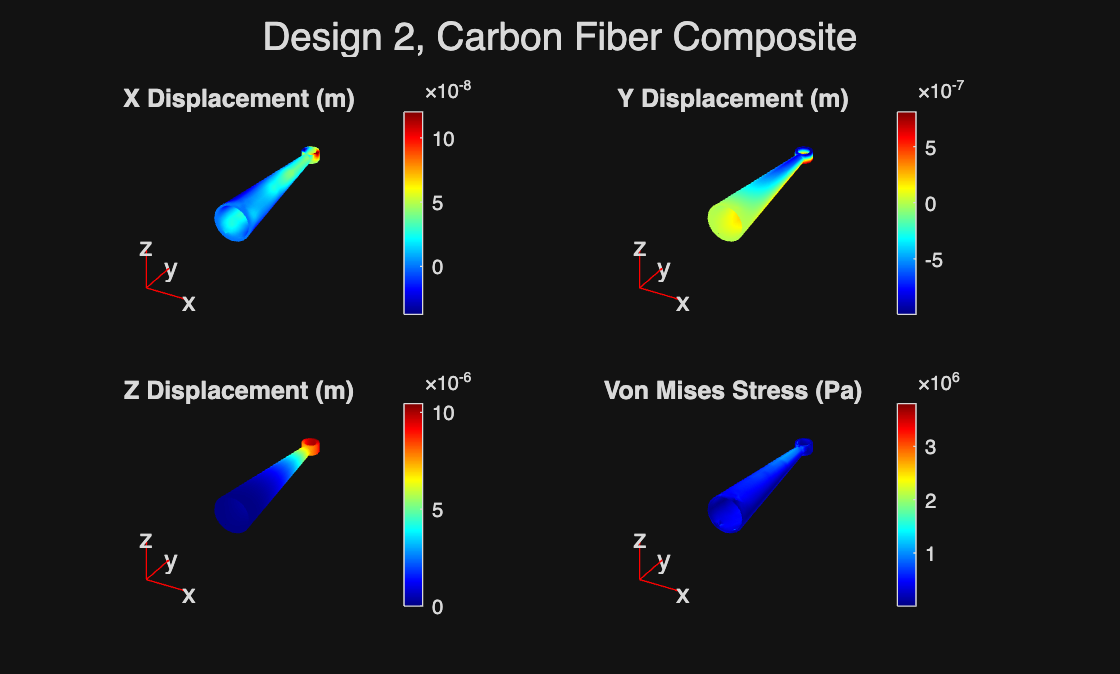

Design 2, Aluminum Alloy: maxDisp=1.06468e-05 m, maxVM=3.97905e+06 Pa, FoS=69.1


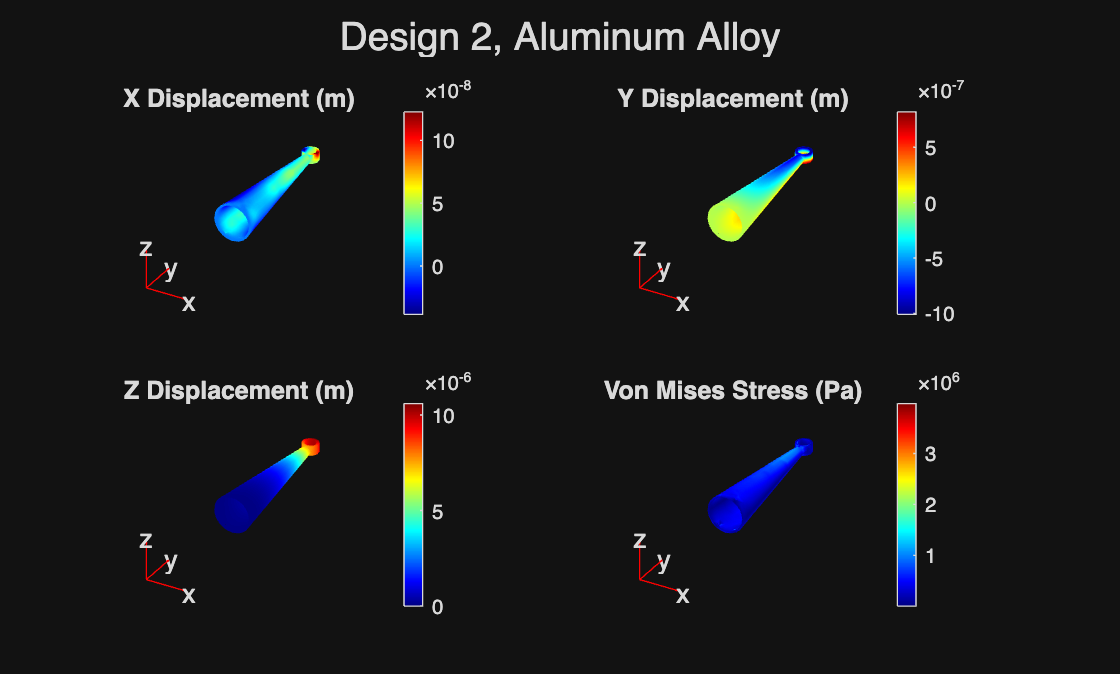

Design 2, Fiberglass Composite: maxDisp=2.94111e-05 m, maxVM=3.70736e+06 Pa, FoS=80.9


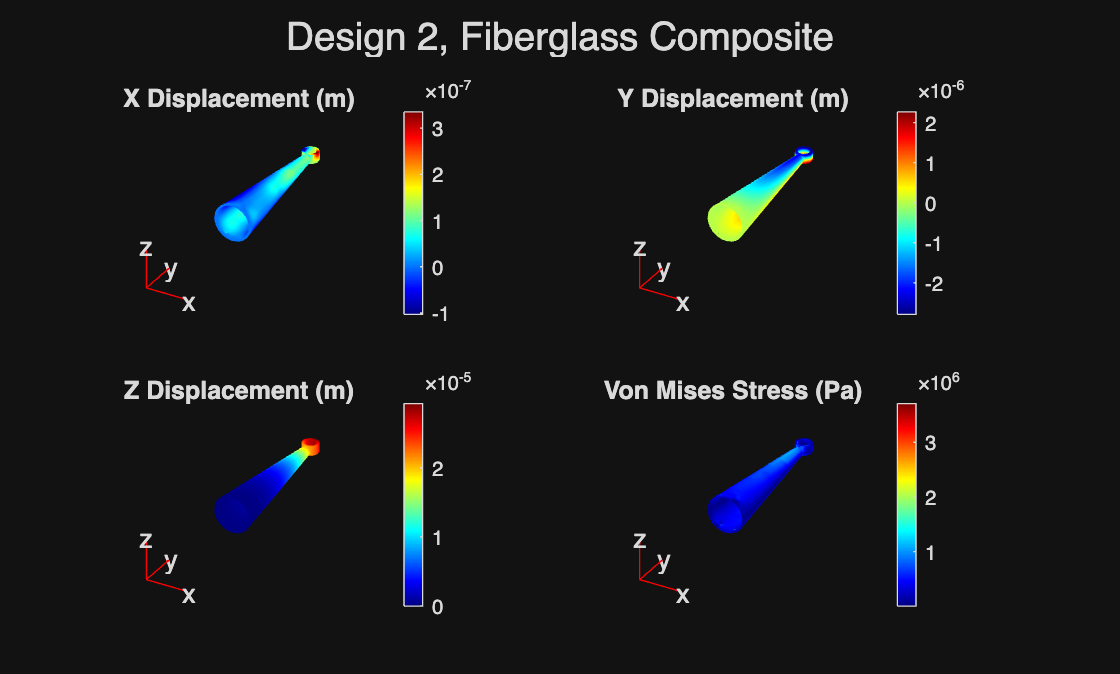

Design 2, PLA Plastic: maxDisp=0.000209733 m, maxVM=4.21281e+06 Pa, FoS=14.2


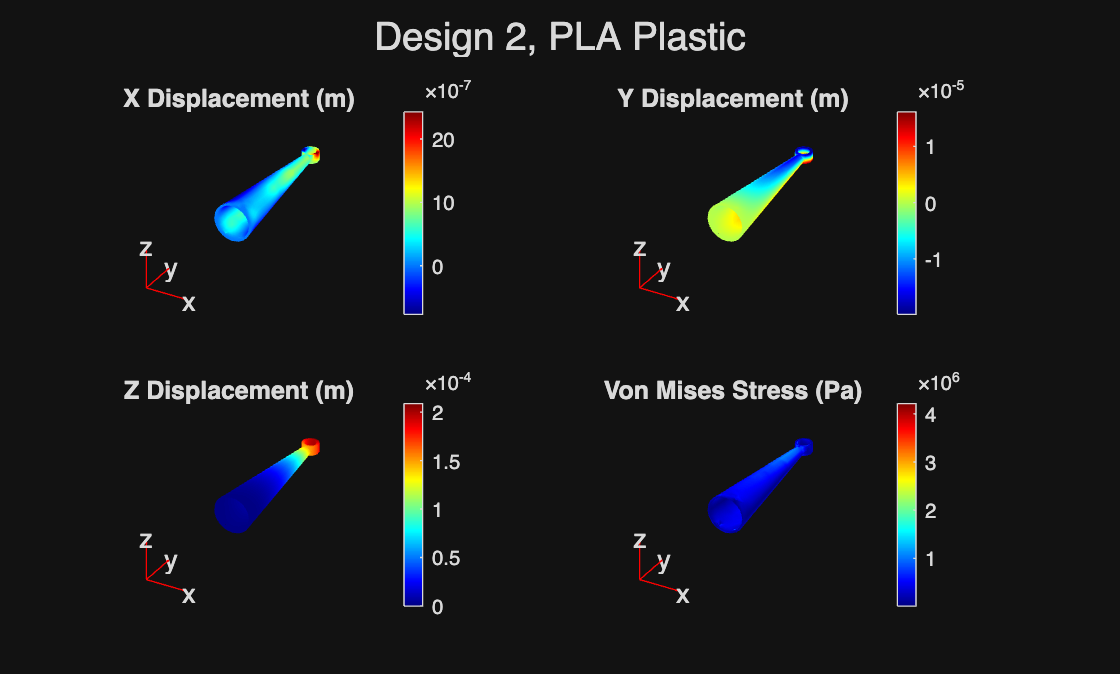

Design 2, ABS Plastic: maxDisp=0.000367136 m, maxVM=4.12723e+06 Pa, FoS=9.69


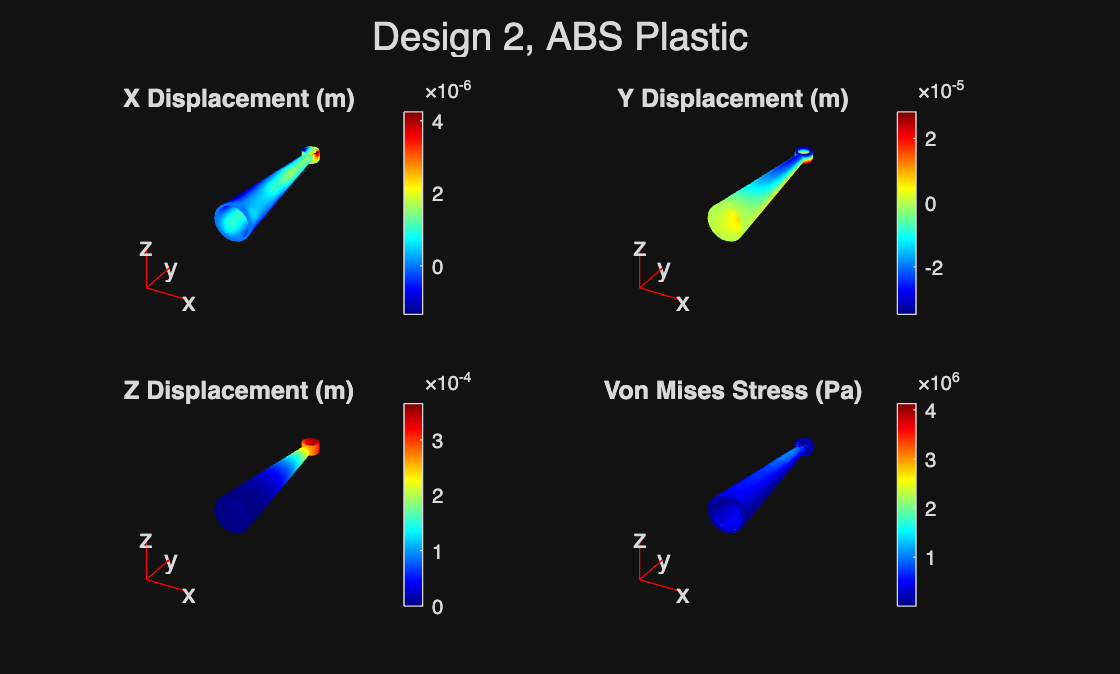

Design 2, Wood: maxDisp=7.34273e-05 m, maxVM=4.12723e+06 Pa, FoS=19.4


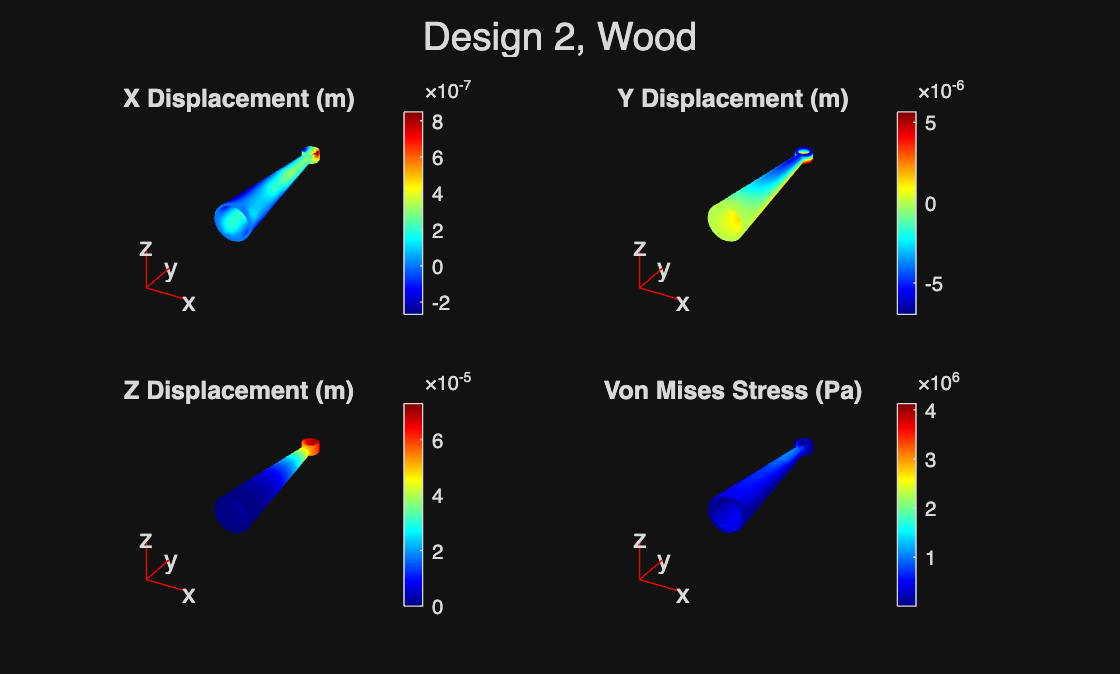

resultsT4 = runFEA(designs, materials, materialNames, motorThrustMax, motorMass, g);

disp(resultsT4)

    Design    Material    MaxDisplacement_m    MaxVonMisesStress_Pa    FactorOfSafety
    ______    ________    _________________    ____________________    ______________

      1          1           4.8817e-06              8.927e+05             672.12    
      1          2           4.9433e-06             8.7796e+05             313.23    
      1          3           1.3684e-05             9.0225e+05              332.5    
      1          4           9.7238e-05             8.6257e+05             69.559    
      1          5            0.0001703             8.6779e+05             46.094    
      1          6            3.406e-05             8.6779e+05             92.188    
      2          1           1.0501e-05              3.802e+06             157.81    
      2          2           1.0647e-05             3.9

 
resultsT4.MeetsFoS = resultsT4.FactorOfSafety >= 1.5;
disp(resultsT4)

    Design    Material    MaxDisplacement_m    MaxVonMisesStress_Pa    FactorOfSafety    MeetsFoS
    ______    ________    _________________    ____________________    ______________    ________

      1          1           4.8817e-06              8.927e+05             672.12         true   
      1          2           4.9433e-06             8.7796e+05             313.23         true   
      1          3           1.3684e-05             9.0225e+05              332.5         true   
      1          4           9.7238e-05             8.6257e+05             69.559         true   
      1          5            0.0001703             8.6779e+05             46.094         true   
      1          6            3.406e-05             8.6779e+05             92.188         true   
      2    

 
 
%% functions
 
function armVol = computeArmVolume(design)
    if isfield(design, 'width')
        armVol = design.length * design.width * design.thickness;
    elseif isfield(design, 'outerDiameter')
        Ro = design.outerDiameter / 2;
        Ri = design.innerDiameter / 2;
        armVol = design.length * pi * (Ro^2 - Ri^2);
    else
        error('design needs either width/thickness or outerDiameter/innerDiameter')
    end
end
 
 
function resultsTable = thrustToWeightAnalysis(designs, materials, baseMass, ...
                                                 numMotors, motorThrustMax, minPayload)
    nD = numel(designs);
    nM = numel(materials);
    rows = cell(nD*nM, 7);
    row = 1;
 
    for d = 1:nD
        armVol = computeArmVolume(designs{d});
        for m = 1:nM
            armMass = armVol * materials(m).rho_kg_m3;
            totalArmMass = 4*armMass;   % 4 arms on the drone
            droneMassNoLoad = baseMass + totalArmMass;
 
            maxThrust = numMotors * motorThrustMax;
            maxPayload = maxThrust/2 - droneMassNoLoad;   % thrust >= 2x weight
 
            meetsMin = maxPayload >= minPayload;
 
            rows(row,:) = {d, m, armMass, totalArmMass, droneMassNoLoad, maxPayload, meetsMin};
            row = row + 1;
        end
    end
 
    resultsTable = cell2table(rows, 'VariableNames', ...
        {'Design','Material','ArmMass_kg','TotalArmMass_kg', ...
         'DroneMass_noPayload_kg','MaxPayload_kg','MeetsMinPayload'});
end
 
 
function feaResults = runFEA(designs, materials, materialNames, motorThrustMax, motorMass, g)
    nD = numel(designs);
    nM = numel(materials);
    rows = cell(nD*nM, 5);
    row = 1;
 
    for d = 1:nD
        design = designs{d};
 
        if isfield(design, 'stlFile') && ~isempty(design.stlFile)
            model = createpde('structural', 'static-solid');
            importGeometry(model, design.stlFile);
 
            % solidworks exports STL in mm by default, everything else
            % here is in meters so we have to scale it down
            if isfield(design, 'cadUnitScale')
                scaleFactor = design.cadUnitScale;
            else
                scaleFactor = 0.001;
            end
            model.Geometry = scale(model.Geometry, scaleFactor);
 
            if isfield(design, 'width')
                tipArea = design.width * design.thickness;
            else
                Ro = design.outerDiameter / 2;
                Ri = design.innerDiameter / 2;
                tipArea = pi * (Ro^2 - Ri^2);
            end
 
        elseif isfield(design, 'width')
            gm = multicuboid(design.width, design.thickness, design.length);
            tipArea = design.width * design.thickness;
            model = createpde('structural', 'static-solid');
            model.Geometry = gm;
 
        else
            Ro = design.outerDiameter / 2;
            Ri = design.innerDiameter / 2;
            C1 = [1; 0; 0; Ro];
            C2 = [1; 0; 0; Ri];
            gd = [C1, C2];
            ns = char('C1', 'C2')';
            sf = 'C1-C2';
            g2D = decsg(gd, sf, ns);
 
            % extrude needs an actual Geometry object, not just the
            % matrix decsg gives back, so build a throwaway 2D model first
            model2D = createpde();
            geometryFromEdges(model2D, g2D);
            gm = extrude(model2D.Geometry, design.length);
            tipArea = pi * (Ro^2 - Ri^2);
            model = createpde('structural', 'static-solid');
            model.Geometry = gm;
        end
 
        generateMesh(model, 'Hmax', design.length/15);
 
        % figure out which faces are the base (fixed) and tip (loaded)
        % automatically instead of hardcoding face numbers, since that
        % changes depending on how the CAD file gets imported
        [baseFaceID, tipFaceID] = identifyBaseTipFaces(model);
 
        figure;
        pdegplot(model, 'FaceLabels', 'on', 'FaceAlpha', 0.5);
        title(sprintf('Design %d geometry (base=%s, tip=%s)', d, ...
              mat2str(baseFaceID), mat2str(tipFaceID)));
 
        thrustForce = motorThrustMax * g;
        motorWeightForce = motorMass * g;
        netForce = thrustForce - motorWeightForce;   % upward net force at tip
        traction = netForce / tipArea;
 
        structuralBC(model, 'Face', baseFaceID, 'Constraint', 'fixed');
 
        for m = 1:nM
            mat = materials(m);
 
            structuralProperties(model, 'YoungsModulus', mat.E_Pa, ...
                                         'PoissonsRatio', mat.nu, ...
                                         'MassDensity', mat.rho_kg_m3);
 
            structuralBoundaryLoad(model, 'Face', tipFaceID, ...
                                    'SurfaceTraction', [0; 0; traction]);
 
            result = solve(model);
 
            dispMag = sqrt(result.Displacement.x.^2 + ...
                           result.Displacement.y.^2 + ...
                           result.Displacement.z.^2);
            maxDisp = max(dispMag);
            maxVM = max(result.VonMisesStress);
            FoS = mat.yieldStrength_Pa / maxVM;
 
            fprintf('Design %d, %s: maxDisp=%.6g m, maxVM=%.6g Pa, FoS=%.3g\n', ...
                    d, materialNames{m}, maxDisp, maxVM, FoS);
 
            rows(row,:) = {d, m, maxDisp, maxVM, FoS};
            row = row + 1;
 
            figure('Name', sprintf('Design %d - %s', d, materialNames{m}));
            subplot(2,2,1);
            pdeplot3D(model, 'ColorMapData', result.Displacement.x);
            title('X Displacement (m)');
            subplot(2,2,2);
            pdeplot3D(model, 'ColorMapData', result.Displacement.y);
            title('Y Displacement (m)');
            subplot(2,2,3);
            pdeplot3D(model, 'ColorMapData', result.Displacement.z);
            title('Z Displacement (m)');
            subplot(2,2,4);
            pdeplot3D(model, 'ColorMapData', result.VonMisesStress);
            title('Von Mises Stress (Pa)');
            sgtitle(sprintf('Design %d, %s', d, materialNames{m}));
        end
    end
 
    feaResults = cell2table(rows, 'VariableNames', ...
        {'Design','Material','MaxDisplacement_m','MaxVonMisesStress_Pa','FactorOfSafety'});
end
 
 
function [baseFaces, tipFaces] = identifyBaseTipFaces(model)
    % finds whichever axis the arm is longest along, then grabs all the
    % faces near each end (within ~8% of the total length) to use as the
    % base/tip regions. using a band instead of trying to find one exact
    % face because the real CAD parts have fillets and cutouts near the
    % ends so there's rarely one clean flat face to grab
    mesh = model.Mesh;
    nodes = mesh.Nodes;
    ranges = max(nodes, [], 2) - min(nodes, [], 2);
    [~, axisIdx] = max(ranges);
 
    coordAll = nodes(axisIdx, :);
    coordMin = min(coordAll);
    coordMax = max(coordAll);
    span = coordMax - coordMin;
    band = 0.08 * span;
 
    nFaces = model.Geometry.NumFaces;
    faceMeanCoord = nan(1, nFaces);
    for f = 1:nFaces
        nodeIDs = findNodes(mesh, 'region', 'Face', f);
        faceMeanCoord(f) = mean(nodes(axisIdx, nodeIDs));
    end
 
    baseFaces = find(faceMeanCoord <= coordMin + band);
    tipFaces = find(faceMeanCoord >= coordMax - band);
 
    if isempty(baseFaces)
        [~, idx] = min(faceMeanCoord);
        baseFaces = idx;
    end
    if isempty(tipFaces)
        [~, idx] = max(faceMeanCoord);
        tipFaces = idx;
    end
end

## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

We recommend Design 1 using Wood, which achieved the highest maximum payload capacity of any tested combination (0.902 kg). Using wood would mean that we pass both the minimum requirement of 0.5 kg, alongside meeting the required safety ratio of 2:1 thrust-to-weight.Design 1's factor of safety with wood was 92.2, far exceeding the 1.5 to 2 structural safety margin. Design 2 was out of the question after review, seeing as it's bulkier design made it too heavy to meet the minimum payload requirement.  Throughout Design 1's material options, we found that factor of safety was never the constraint in the design; even the weakest material tested (ABS) had a FoS of 46 (well above the 1.5 to 2 requirement). Our design favored lower density materials like wood, ABS, and PLA over stronger but denser options like carbon fiber. 

What are some limitations of your work?

Most of our limitations come from not actually having the entirety of the drone arm fully constructed in front of us to analyze. We constructed the drone without accounting for external factors in the real world like weather or temperature. For example, wind or low temperatures with high moisture might affect the structural integrity greatly depending on the severity of both of these factors. On top of that, we built the drone arm without accounting for many of the parts that hold the drone arm to the drone body, like the bolts that keep the arm in place. We simply just do not have the real drone in front of us to look at and determine what parts we completely missed within our initial design. Our calculations also depend on the constructed dimensions through CAD rather than the real world dimensions, meaning the parts that have empty space and removed material aren't correctly accounted for; likely overestimating the true payload capacity for our drone. 

What are practical next steps?

We think that the best next steps would be to actually build the drone that we envisioned with our designs. Having the real world drone would mean that we are working with and accounting for external factors and missing parts in our initial designs, ultimately allowing us to attempt to fix our current errors with our drone. Gathering data through various trials and errors with our real drone would allow us to accurately determine the true payload, which we could then use to compare to our simulated drone designs within this project. We would actually be able to see how far off we were with our current work by using a tangible version of our designs.